clear
% Define the folder path
folderPath = 'HDR/JPG'; % Adjust the path as necessary

% Create an imageDatastore for all JPG files in the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.jpg');

% Display the number of images found
numImages = numel(imds.Files);
disp(['Number of JPG images found: ', num2str(numImages)]);

Number of JPG images found: 14


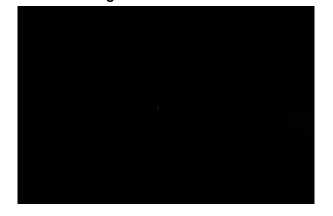


% Read the i-th image from the datastore
img = readimage(imds, 1);

% Display the image
imshow(img);
title('Image from the Datastore');

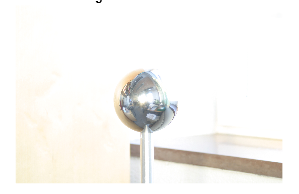

img = readimage(imds, numImages);
imshow(img);
title('Image from the Datastore');





%Ranom Sampling of pixels
[H, W, C] = size(img); % read image Height, Width, Channel. Assumed same for all images duuh

numSamples = 200;
rng(0);
% meshgrid avoids sample clustering. grid bias + random.
[Xs, Ys] = meshgrid(round(linspace(1,W,round(sqrt(numSamples)))), round(linspace(1,H,sqrt(numSamples))));
coord = [Xs(:),Ys(:)];
if size(coord, 1) < numSamples
    extra = numSamples - size(coord,1);
    randCoord = [randi(W, extra, 1), randi(H, extra, 1)];
    coord = [coord; randCoord];
else
    coord = coord(1:numSamples,:);
end
% I orginal artikeln så nämns det att de kastade även ut väldigt saturerade
% värden dvs 255


exposureTimes = zeros(numImages,1);
for j = 1:numImages
    info = imfinfo(imds.Files{j});
    exposureTimes(j) = info.DigitalCamera.ExposureTime;
end

B = log(exposureTimes);

% Hat weight 
Zmin = 0;
Zmax = 255;
Zmid = Zmax/2;
wvec = zeros(256, 1);
for z = Zmin:Zmax
    if z <= Zmid
        wvec(z+1) = z - Zmin;
    else
        wvec(z+1) = Zmax -z;
    end
end



% Read camera curve, named gfun
load("HDR\gfun.mat")



Z = zeros(numSamples, numImages, 'uint8'); %preallocate Z
for j = 1:numImages
    Ij = readimage(imds, j);
    gray = rgb2gray(Ij); % grayscale
    for i = 1:numSamples
        Z(i,j) = gray(coord(i,2), coord(i,1));
    end
end

lambda = 10;
[g, lE] = gsolve(Z, B, lambda, wvec);

g 

g =    -6.4371
   -5.5653
   -4.6936
   -4.1602
   -3.8413
   -3.6147
   -3.4393
   -3.2979
   -3.1818
   -3.0742


lE

lE =     1.8063
    1.8570
    1.8531
    1.8225
    1.7754
    1.7673
    1.6789
    1.6631
    1.5743
    1.5242




% go through each image
% for j = 1:numImages
%     % create a vector of each image
%     pixels = 2
%     for i = 1:pixels
%         [g,lE]=gsolve(Z,B,l,w)
%     end
% end



%Load all grayscale images 
for j = 1:numImages 
    Ij = imread(imds.Files{j}); 
    Ij = rgb2gray(Ij); % convert to grayscale 
    Ij = im2uint8(Ij); % 0–255 range 
    if j == 1 
        [H,W] = size(Ij);
        images = zeros(H,W,numImages,'uint8');
    end 
    images(:,:,j) = Ij;
end 

%reconstruct image in .hdr (Radiance) 
lnE = zeros(H,W);

for y = 1:H
    for x = 1:W 
        num = 0;
        den = 0;
        for j = 1:numImages
            z = double(images(y,x,j));
            wij = wvec(z+1);
            num = num + wij * (g(z+1) - B(j));
            den = den + wij;
        end 
        if den > 0
            lnE(y,x) = num / den;
        else
            lnE(y,x) = 0;
        end 
    end 
end


% vad ska vi göra med kameran btw?
HDR = exp(lnE)

HDR =     6.1163    6.1173    6.0380    6.0065    6.0279    5.9819    5.9838    6.0576    5.9645    5.8842    5.8889    5.9436    5.9900    5.9926    6.0284    6.0638    5.9700    6.0656    6.0476    5.9967    6.0179    6.0002    5.9581    6.0366    6.0027    6.0030    6.0284    6.0399    6.0203    6.0525    6.0735    6.0489    6.1028    6.0988    6.1719    6.2244    6.1743    6.1465    6.2494    6.2764    6.2706    6.2674    6.3169    6.3465    6.3791    6.3934    6.4065    6.3971    6.3465    6.3454
    6.0474    6.0609    6.0601    6.0088    6.0344    6.0515    6.0311    6.0232    5.9901    5.9163    5.8947    5.9431    6.0008    5.9930    5.9973    5.9839    5.9499    6.0441    6.0440    6.0503    6.0695    6.0640    6.0180    6.0670    5.9915    5.9828    5.9744    6.0384    6.0492    6.0322    6.0118    5.9708    6.0821    6.1264    6.1363    6.1390    6.1469    6.1907    6.2616    6.2731    6.3219    6.2953    6.2587    6.2631    6.3562    6.4177    6.3844    6.3355    6.2766   

HDR3 = repmat(HDR, [1, 1, 3])

HDR3 = HDR3(:,:,1) =

  Columns 1 through 999

    6.1163    6.1173    6.0380    6.0065    6.0279    5.9819    5.9838    6.0576    5.9645    5.8842    5.8889    5.9436    5.9900    5.9926    6.0284    6.0638    5.9700    6.0656    6.0476    5.9967    6.0179    6.0002    5.9581    6.0366    6.0027    6.0030    6.0284    6.0399    6.0203    6.0525    6.0735    6.0489    6.1028    6.0988    6.1719    6.2244    6.1743    6.1465    6.2494    6.2764    6.2706    6.2674    6.3169    6.3465    6.3791    6.3934    6.4065    6.3971    6.3465    6.3454    6.3263    6.3339    6.2465    6.2597    6.2630    6.2904    6.1956    6.1444    6.1654    6.1398    6.0676    6.0246    6.0472    6.1079    5.9148    5.9045    5.9606    6.0088    6.0322    6.0421    6.1195    6.1138    6.1145    6.1390    6.1825    6.2268    6.1984    6.1717    6.1660    6.1659    6.1456    6.2446    6.2696    6.2987    6.2237    6.1946    6.1730    6.2692    6.2405    6.2379    6.2722    6.3689    6.3407    6.2788    6.3167   

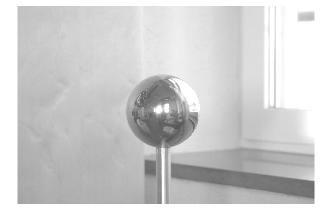

hdrwrite(single(HDR3), 'result.hdr'); 
%Result blir nästan helt vit när man kollar i photoshop
% hade dock inte hdr-läge på men men. 

% Nu använder den:
% edge-preserving decompositions for multiscale tone and detail manipulation
% tonemap men vi ska göra egen eller något sånt. 
LDR_final = tonemapfarbman(HDR);
imshow(LDR_final)

% This section is from the paper 
% HDR-Debevec-97.pdf


% gsolve.m − Solve for imaging system response function
%
% Given a set of pixel values observed for several pixels in several
% images with different exposure times, this function returns the
% imaging system’s response function g as well as the log film irradiance
% values for the observed pixels.
%
% Assumes:
%
% Zmin = 0
% Zmax = 255
%
% Arguments:
%
% Z(i,j) is the pixel values of pixel location number i in image j
% B(j) is the log delta t, or log shutter speed, for image j
% l is lamdba, the constant that determines the amount of smoothness
% w(z) is the weighting function value for pixel value z
% 
% Returns:
%
% g(z) is the log exposure corresponding to pixel value z
% lE(i) is the log film irradiance at pixel location i
%

function [g,lE]=gsolve(Z,B,l,w)
    n = 256;
    A = zeros(size(Z,1)*size(Z,2)+n+1,n+size(Z,1));
    b = zeros(size(A,1),1);
    %% Include the data−fitting equations
    k = 1;
    for i=1:size(Z,1)
        for j=1:size(Z,2)
            wij = w(Z(i,j)+1);
            A(k,Z(i,j)+1) = wij; 
            A(k,n+i) = -wij; 
            b(k,1) = wij * B(j);
            k=k+1;
        end
    end
    %% Fix the curve by setting its middle value to 0
    A(k,129) = 1;
    k=k+1;
    %% Include the smoothness equations
    for i=1:n-2
     A(k,i)=l*w(i+1); A(k,i+1)=-2*l*w(i+1); A(k,i+2)=l*w(i+1);
     k=k+1;
    end
    %% Solve the system using SVD
    x = A\b;
    g = x(1:n);
    lE = x(n+1:size(x,1));
end
